# Init

clear
addpath 'Functions'
addpath 'Functions/reticolo_allege'
load('Functions\BasicOptParm.mat','OptParm')

## Parallel setting

if max(size(gcp)) == 0 % parallel pool needed
    parpool('local',48);
end 
poolobj = gcp('nocreate');
poolsize = poolobj.NumWorkers;

# Optimization using genetic algorithm

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


Optimization terminated: time limit exceeded.


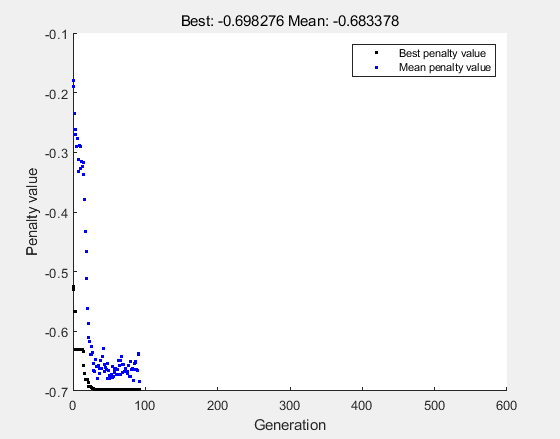

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.



% 厚度
OptParm.Geometry.Thickness = 2800;

RunTimes = 20;


fun = @(x) -FomReticolo1D(x,OptParm);
nvars = length(OptParm.Optimization.Start);
IntCon = 1:nvars;
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1,nvars);
ub = (OptParm.Geometry.Level-1)*ones(1,nvars);
nonlcon = [];
options = optimoptions('ga',...
    'UseParallel', true,...
    'PlotFcn','gaplotbestf',...
    'MaxTime',6000);

x_list = {};
for ii=1:RunTimes
    figure('Position',[0 0 250 150])
    x = ga(fun,nvars,A,b,Aeq,beq,lb,ub,nonlcon,IntCon,options);
    x_list = [x_list,x];
    drawnow
end

save("StructureGA_list.mat",'x_list')

# Simulation validation

% 读取
load("StructureGA.mat",'x')
load('Functions\BasicOptParm.mat','OptParm')
% 波长
wavelength_list = [1500,1550,1600];
% 无偏差
OptParm.Optimization.Robustness.StartDeviation = [0]; % Starting height deviation values
OptParm.Optimization.Robustness.Weights = [1];
% 遍历
FOM_list = zeros(length(wavelength_list),2);
for ii = 1:length(wavelength_list)
    OptParm.Input.Wavelength = wavelength_list(ii);
    OptParm.Input.Polarization = 'TM';
    FOM_list(ii,1) = FomReticolo1D(x,OptParm);
    OptParm.Input.Polarization = 'TE';
    FOM_list(ii,2) = FomReticolo1D(x,OptParm);
end
% 显示结构
figure('Position',[0 0 300 150])
bar(x,1)
ylabel('Level')
ylim([0 (OptParm.Geometry.Level-1)])

figure('Position',[0 0 250 150])
bar(wavelength_list,FOM_list);
xlabel('Wavelength/nm')
legend('TM','TE','Location','northeastoutside')

figure('Position',[0 0 250 100])
heatmap(wavelength_list,{'TM','TE'},FOM_list')
xlabel('Wavelength/nm')

# List Simulation validation

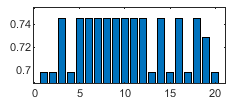

% 读取
load("StructureGA_list.mat",'x_list')
Eff_avg = zeros(1,length(x_list));
parfor ii=1:length(x_list)
    Eff_avg(ii) = FomReticolo1D(x_list{ii},OptParm);
end
figure('Position',[0 0 250 100])
bar(Eff_avg);
ylim([min(Eff_avg)-0.01,max(Eff_avg)+0.01])

# See geometry

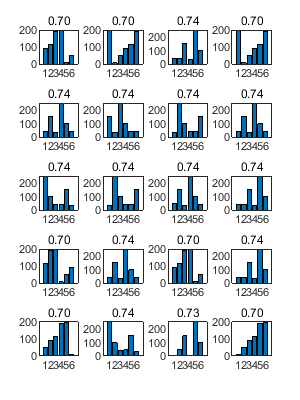

figure('Position',[0 0 300 400])
t = tiledlayout('flow','TileSpacing',"compact");
for ii=1:length(x_list)
    nexttile
    bar(x_list{ii});
    title(sprintf('%.2f',Eff_avg(ii)))
end